%%向下重采样
clear all
t0=0.01;%原采样间隔
Fs0=1/t0;
f0=Fs0/2; %原截止频率=1/2采样率
%t1=0.02;%新采样间隔
t1=0.02;
Fs1=1/t1;%新采样率
ratio=t1/t0;   %新采样间隔/原采样间隔
N0=4096;%原数据点数
N1=floor(N0*t0/t1);
n=0:N0-1;t=n/Fs0;
zeta=Fs1/(2*f0);  % 重采样的低通滤波器参数
%zeta=1
n1=0:N1-1;t1=n1/Fs1;
xn0=sin(2*pi*1*t)+0.5*sin(2*pi*30*t);
xn1=sin(2*pi*1*t1)+0.5*sin(2*pi*30*t1);
%xn0=sin(2*pi*0.1*t);


Nf=100; 
for m=floor(Nf/ratio)+Nf+1:N1-floor(Nf/ratio)-1
    x(m)=0;
    for n=floor(m*ratio)-Nf:1:floor(m*ratio)+Nf
        x(m)=x(m)+zeta*xn0(n)*sinc(zeta*(m*ratio-n));
    end
end
xl=length(x);
n1=0:N1-1;tt1=n1/Fs1;
nn1=length(n1);
ntt1=length(tt1);
nx=length(x);
ty=0:0.001:4096*t0-Nf/Fs0;
z=sin(2*pi*1*(ty+Nf/Fs0-0.01))+0.5*sin(2*pi*30*(ty+Nf/Fs0-0.01));
%z=sin(2*pi*0.1*(ty+Nf/Fs0))
n=0:1:(N0-1);
f=n*Fs0/N0;
xn0fft=abs(fft(xn0,N0));


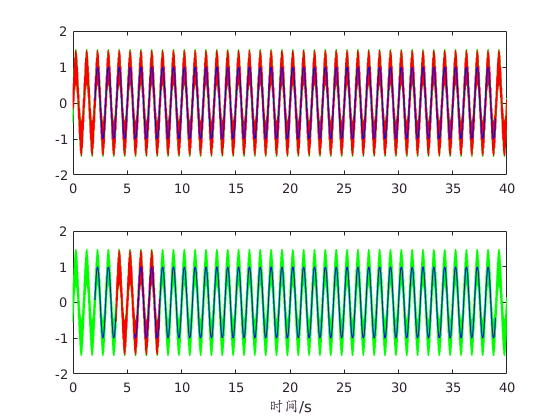

figure(1);
subplot(2,1,1)
plot(ty,z,'g')
hold on
t100 = t(1+1:N0-Nf);
xn0100 = xn0(1+Nf:N0-1);
plot(t100,xn0100,'r');
hold on
%蓝线是向下重采样的结果.在重采样的同时已实现了低通滤波
tt150 = tt1(floor(Nf/ratio)+Nf+1-Fs1+1:N1-floor(Nf/ratio)-1-Fs1+1);
x50 = x(floor(Nf/ratio)+Nf+1:N1-floor(Nf/ratio)-1);
plot(tt150,x50,'b');
hold on

shoLength = floor(length(ty)/10);
subplot(2,1,2)
shoLength = floor(length(ty)/10);
plot(ty(shoLength:shoLength*2),z(shoLength:shoLength*2),'g')
hold on  
shoLength = floor(length(t100)/10);
plot(t100(shoLength:shoLength*2),xn0100(shoLength:shoLength*2),'r');
hold on
shoLength = floor(length(tt150)/10);
plot(tt150(shoLength:shoLength*2),x50(shoLength:shoLength*2),'b');
hold on
% 重采样+低通滤波
xlabel('时间/s')

figure(2);
subplot(4,1,1);
plot(f,xn0fft*2/N0);
title('(a)   100sps采样的频谱')
zfft=abs(fft(z,32768));
n=0:1:(32768-1);
fz=n/(32768*0.001);
subplot(4,1,2);
plot(fz,2*zfft/32768);title('(b)   1000sps采样的频谱');
subplot(4,1,4)
Nx=length(x)

Nx = 1997

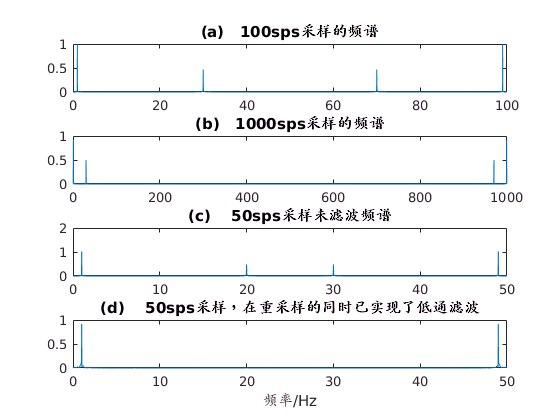

xfft=abs(fft(x));
n=0:1:Nx-1;
fx=n*Fs1/Nx;
plot(fx,2*xfft/Nx);
xlabel('频率/Hz');
title('(d)    50sps采样，在重采样的同时已实现了低通滤波');
subplot(4,1,3);
xn1fft=abs(fft(xn1));
fxn1=n1*Fs1/N1;
plot(fxn1,xn1fft*2/Nx);
title('(c)    50sps采样未滤波频谱');

figure(3);
%用样条函数（spline)模拟信号恢复
%Dt=0.00005;t=-0.005:Dt:0.005;
subplot(2,1,1)
plot(t(1:100),xn0(1:100));
title('x=sin(2*pi*1*t)+0.5*sin(2*pi*30*t),采样率100sps');
subplot(2,1,2)
ty1=0:0.001:4096*t0;
n=0:N0-1;
t=n/Fs0;
nty1=length(ty1)

nty1 = 40961

nxn0=length(xn0)

nxn0 = 4096

nnt0=length(n*t0)

nnt0 = 4096

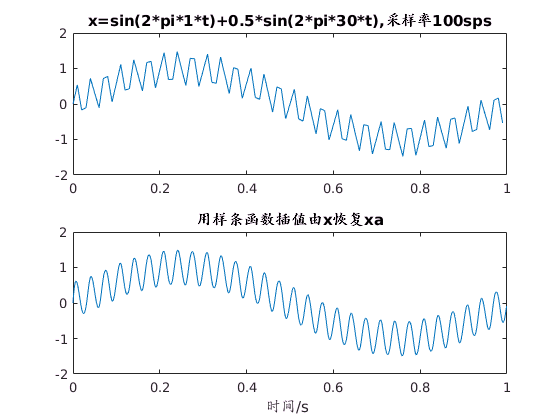

xa=spline(n*t0,xn0,ty1);
plot(ty1(1:1000),xa(1:1000))
title('用样条函数插值由x恢复xa');
xlabel('时间/s ');